clc; close all;

% Motor Constants
noLoadCurrent = 2.1; % Amp
noLoadSpeed = 5600; % RPM
noLoadSpeed_rad = noLoadSpeed * 2*pi / 60; % rad/s
Km = 0.04025; % Nm / Amp

BM = 30000*0.1*noLoadCurrent * Km / noLoadSpeed_rad; % Nms

R_terminal = 0.3; % 0.19; % Ohms
L_terminal = 188e-6; %Henrys

s = tf('s');

% Position to Angle Transforms

% Z = zeros(2);
% D = [1,1;1,-1]*0.035/2;
% D_inv = inv(D);

% System Constants
x_moment = 8750;
y_moment = 17000;
% JM = sqrt(x_moment^2 + y_moment^2); %g*cm^2
% JM = JM / 1000 / 100^2; %kg*m^2

JM = 400*612 / 1000 / 100^2; %kg*m^2

Ym = 1 / (JM * s + BM);
rad_sec_to_rpm = 60/(2*pi);

% Controller Parameters
k_p = 1.0; % 15;
k_i = 0; %10;
k_d = 0.0003; %.5;

csv_signature = "BEGIN CSV";

folder_name = "../BluePill-LLC/H-bot pwm test data/X";
all_files = dir(folder_name);
most_recent_file = all_files(end-0).name

most_recent_file = '20230323_time1544_pwm70.csv'


file_name = fullfile(folder_name, most_recent_file);

file_contents = fileread(file_name);

content_begin = regexp(file_contents, csv_signature);
content_end = regexp(file_contents, '\n.*$', 'end');

if isempty(content_begin)
    disp("Did not find CSV signature in file")
end

data = file_contents(content_begin+11:content_end);

FID = fopen('temp.csv', 'w');
fprintf(FID, data);
fclose(FID);

data = readtable('temp.csv', 'Delimiter', ',');

% disp(table.Properties.VariableNames);
% Compute delta t
data.delta_t_ms_ = [NaN; diff(data.Time_ms_)];
% disp(table.Left_PWM(1))

% Compute Left_Actual_deg_ and Right_Actual_deg_
data.Left_Actual_deg_ = 0 - data.Left_Error_deg_;
data.Right_Actual_deg_ = 0 - data.Right_Error_deg_;

% Compute X and Y actual
D = [1,1;1,-1]*0.035/2;
xy = rowfun(@(x,y) 100*(D*[x;y])', data(:,{'Left_Actual_deg_','Right_Actual_deg_'}));
xy = table2array(xy);

data = addvars(data, xy(:,1), xy(:,2), 'NewVariableNames', {'X_Actual_cm_','Y_Actual_cm_'});
% Compute X_Velocity and X_Target_Velocity
data.X_Velocity_cm_s_ = [NaN; diff(data.X_Actual_cm_) ./ data.delta_t_ms_(2:end) .* 1000];
data.X_Target_Velocity_cm_s_ = [NaN; diff(data.X_Target_cm_) ./ data.delta_t_ms_(2:end) .* 1000];

% Compute Y_Velocity and Y_Target_Velocity
data.Y_Velocity_cm_s_ = [NaN; diff(data.Y_Actual_cm_) ./ data.delta_t_ms_(2:end) .* 1000];
data.Y_Target_Velocity_cm_s_ = [NaN; diff(data.Y_Target_cm_) ./ data.delta_t_ms_(2:end) .* 1000];

% for i = 1:length(data.X_Target_cm_)

% [data.X_Actual_cm_, data.Y_Actual_cm_] = pagemtimes(D, [data.Left_Actual_deg_; data.Right_Actual_deg_] * pi / 180);

% Compute Left_Velocity and Right_Velocity
data.Left_Velocity_deg_s_ = [NaN; diff(data.Left_Actual_deg_) ./ data.delta_t_ms_(2:end) .* 1000];
data.Right_Velocity_deg_s_ = [NaN; diff(data.Right_Actual_deg_) ./ data.delta_t_ms_(2:end) .* 1000];

figure;
set(gcf,'visible','on','position',[750 100 600 400]);
hold on
plot(data.Time_ms_ / 1000, -data.Left_Velocity_deg_s_);
plot(data.Time_ms_ / 1000, data.Right_Velocity_deg_s_);
ylabel('Angular Velocity')
out = sim('H_bot_model_PWM','SaveOutput','on','OutputSaveName','yout','SaveFormat','Dataset');

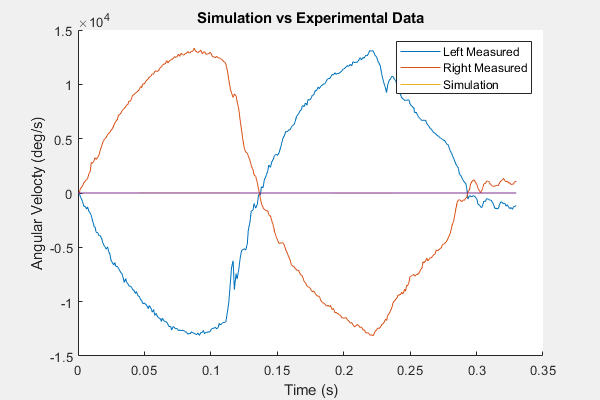


plot(out.simout.Time, out.simout.Data);
% xlim([0 0.25])
title('Simulation vs Experimental Data');
legend({'Left Measured', 'Right Measured', 'Simulation'});
xlabel("Time (s)");
ylabel("Angular Velocty (deg/s)");

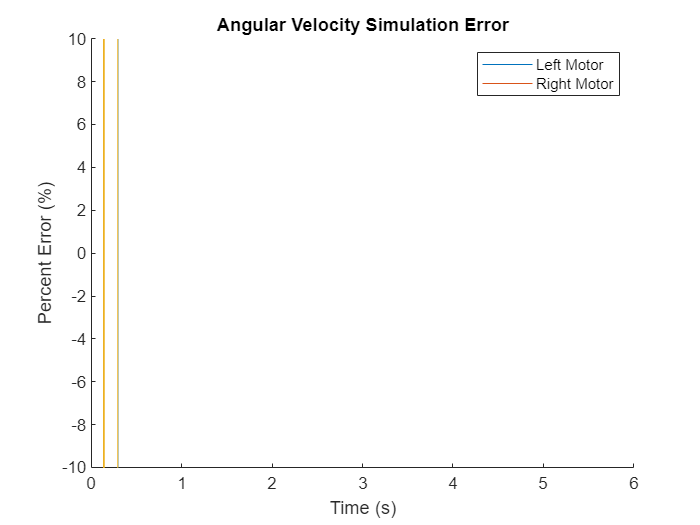



figure
% set(gcf, "visible", "on", 'position', [100 100 600 400])

resampledSim = resample(timeseries(out.simout), data.Time_ms_/1000);
hold on
plot(resampledSim.Time, movmean((-data.Left_Velocity_deg_s_ - resampledSim.Data)./resampledSim.Data, 10)*100)
plot(resampledSim.Time, movmean((data.Right_Velocity_deg_s_ - resampledSim.Data)./resampledSim.Data, 10)*100)
legend({'Left Motor', 'Right Motor'})
xlim([0 6])
ylim([-10 10])
title('Angular Velocity Simulation Error')
xlabel('Time (s)')
ylabel('Percent Error (%)')